r = 0.05;
l = 0.18;
u = 15*ones(1, 126);
w = 1*ones(1, 126);
N = length(u);
tf = N;
ts = 0.05;
t = linspace(0, ts, N);
x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);
x1(1) = 0;
y1(1) = 0;
phi(1) = 0;
hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1); 
for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

    wr_k = (2*u(k) + w(k)*l) / (2*r);
    wl_k = (2*u(k) - w(k)*l) / (2*r);
    fprintf('t = %.2f s | ω_R = %.2f rad/s | ω_L = %.2f rad/s\n', k*ts, wr_k, wl_k);


end

t = 0.05 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.10 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.15 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.20 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.25 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.30 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.35 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.40 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.45 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.50 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.55 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.60 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.65 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.70 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.75 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.80 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.85 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.90 s | ω_R = 301.80 rad/s | ω_L = 298.20 rad/s
t = 0.95 s | ω_R = 301.80 rad/s | ω_L = 298.20

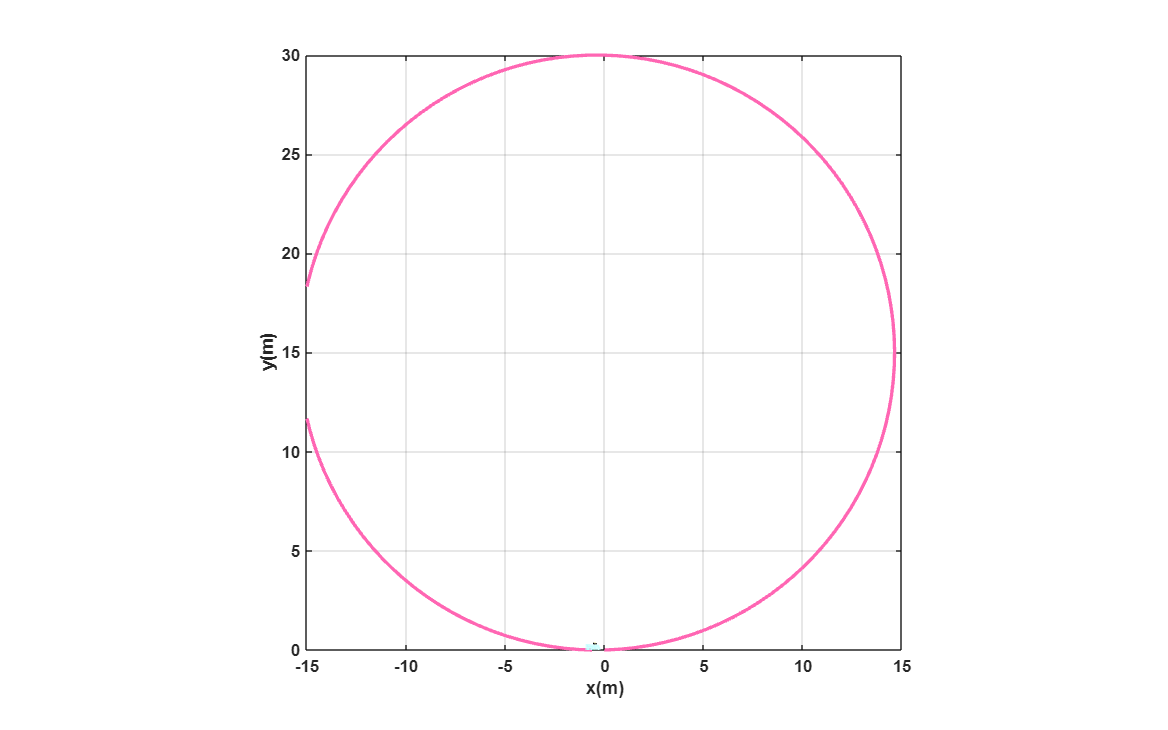

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-15 15 0 30 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);
step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'Color', [1 0.4 0.7],'lineWidth',2);
    
    pause(ts);

end

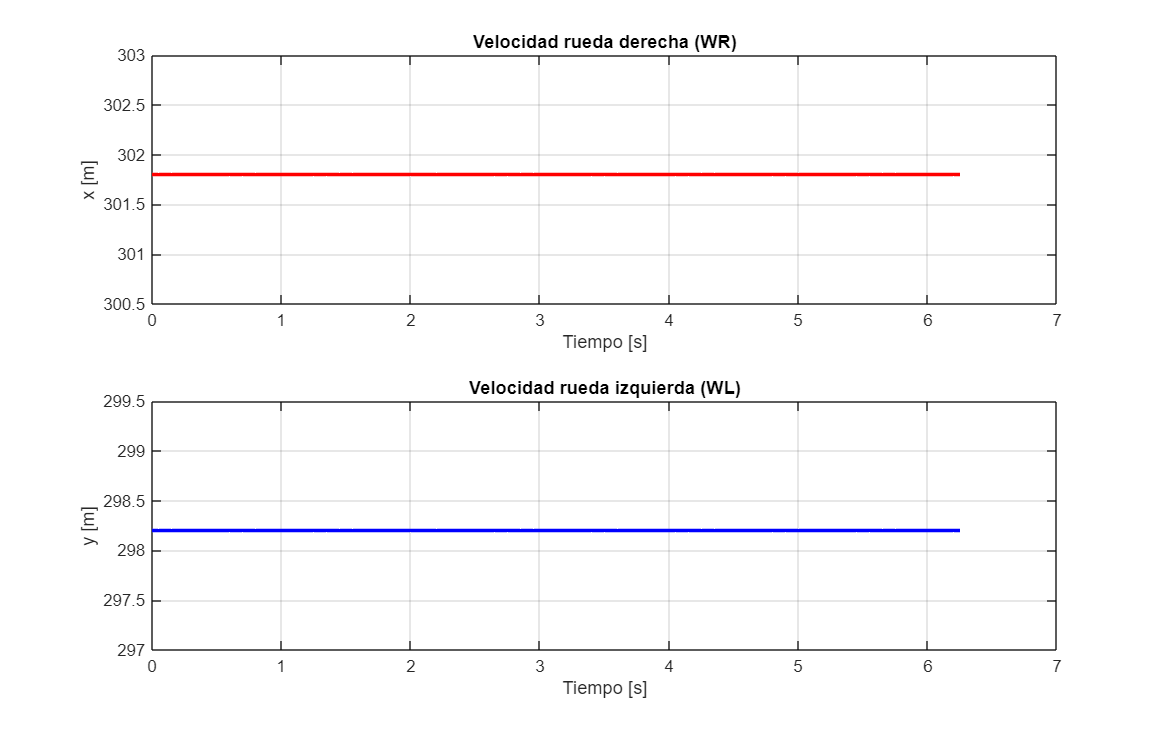

wr = (2*u + w*l) / (2*r);
wl = (2*u - w*l) / (2*r);

graph6 = figure;
set(graph6, 'position', sizeScreen);

subplot(2,1,1)
plot((0:N-1)*ts, wr, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Velocidad rueda derecha (WR)');
grid on;

subplot(2,1,2)
plot((0:N-1)*ts, wl, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Velocidad rueda izquierda (WL)');
grid on;